# Convert MIDI Files into MIDI Messages

## Read MIDI File

MIDI_file_name = './ExampleFiles/신호등.mid';

readme = fopen(MIDI_file_name);
[readOut, byteCount] = fread(readme);
fclose(readme);
ticksPerQNote = polyval(readOut(13:14),256);

### Parse MIDI Track Chunk

% Initialize values
chunkIndex = 14;     % Header chunk is always 14 bytes
ts = 0;              % Timestamp - Starts at zero
BPM =97;
time_signature = 4; % ex) 4/4 or 3/4 ...
msgArray = [];


% Parse track chunks in outer loop
while chunkIndex < byteCount
    
    % Read header of track chunk, find chunk length   
    % Add 8 to chunk length to account for track chunk header length
    chunkLength = polyval(readOut(chunkIndex+(5:8)),256)+8;
    
    ptr = 8+chunkIndex;             % Determine start for MIDI event parsing
    statusByte = -1;                % Initialize statusByte. Used for running status support
    
    % Parse MIDI track events in inner loop
    while ptr < chunkIndex+chunkLength
        % Read delta-time
        [deltaTime,deltaLen] = findVariableLength(ptr,readOut);  
        % Push pointer to beginning of MIDI message
        ptr = ptr+deltaLen;
        
        % Read MIDI message
        [statusByte,messageLen,message] = interpretMessage(statusByte,ptr,readOut);
        % Extract relevant data - Create midimsg object
        [ts,msg] = createMessage(message,ts,deltaTime,ticksPerQNote,BPM);
        
        % Add midimsg to msgArray
        msgArray = [msgArray;msg];
        % Push pointer to next MIDI message
        ptr = ptr+messageLen;
    end
    
    % Push chunkIndex to next track chunk
    chunkIndex = chunkIndex+chunkLength;
end
disp(msgArray)

  1502�1 midimsg array:
    NoteOn          Channel: 1  Note: 47  Velocity: 62  Timestamp: 4.94845  [ 90 2F 3E ]
    NoteOn          Channel: 1  Note: 54  Velocity: 62  Timestamp: 4.94845  [ 90 36 3E ]
    NoteOn          Channel: 1  Note: 59  Velocity: 62  Timestamp: 4.94845  [ 90 3B 3E ]
    NoteOn          Channel: 1  Note: 61  Velocity: 62  Timestamp: 4.94845  [ 90 3D 3E ]
    NoteOn          Channel: 1  Note: 66  Velocity: 62  Timestamp: 4.94845  [ 90 42 3E ]
    NoteOff         Channel: 1  Note: 59  Velocity: 64  Timestamp: 6.49485  [ 80 3B 40 ]
    NoteOn          Channel: 1  Note: 59  Velocity: 62  Timestamp: 6.49485  [ 90 3B 3E ]
    NoteOff         Channel: 1  Note: 61  Velocity: 64  Timestamp: 6.49485  [ 80 3D 40 ]
    NoteOff         Channel: 1  Note: 66  Velocity: 64  Timestamp: 6.49485  [ 80 42 40 ]
    NoteOff         Channel: 1  Note: 47  Velocity: 64  Timestamp: 6.80412  [ 80 2F 40 ]
    NoteOff         Channel: 1  Note: 54  Veloc

## Note on Midi Array

on_msgArray = msgArray(find(int8([msgArray.Type]) == 1));
off_msgArray = msgArray(find(int8([msgArray.Type]) == 2));

% note_list = [on/off, Note, Velocity, Timestamp]
note_list = zeros(length(on_msgArray) + length(off_msgArray), 4);
on_list = ones(1, length([on_msgArray.Note]));
off_list = zeros(1, length([off_msgArray.Note]));
note_list(1:length(on_msgArray), :) = [on_list; on_msgArray.Note; on_msgArray.Velocity; on_msgArray.Timestamp].';
note_list(length(on_msgArray)+1:length(on_msgArray) + length(off_msgArray), :) = [off_list; off_msgArray.Note ; off_msgArray.Velocity ; off_msgArray.Timestamp].';
note_list = sortrows(note_list, 4);
note_list(:, 4) = round(note_list(:, 4).*1000);
total_time = max(note_list(:, 4))

total_time = 113814

disp(note_list)

           1          47          62        4948
           1          54          62        4948
           1          59          62        4948
           1          61          62        4948
           1          66          62        4948
           1          59          62        6495
           0          59          64        6495
           0          61          64        6495
           0          66          64        6495
           1          54          62        6804
           0          47          64        6804
           0          54          64        6804
           1          66          62        6959
           0          59          64        6959
           1          45          62        7423
           1          57          62        7423
           1          61          62        7423
           1          64          62        7423
           0          54          64        7423
           0          66          64        7423
           1        

off_time = zeros(1, length([off_msgArray.Note]));
only_on_list = [on_msgArray.Note; on_msgArray.Velocity; on_msgArray.Timestamp; off_time].';
only_on_list(:, 3) = round(only_on_list(:, 3).*1000);
node_off = [off_msgArray.Note; off_msgArray.Timestamp].';
node_off(:, 2) = round(node_off(:, 2).*1000);

for i = 1:length(node_off)
    off_note = node_off(i, 1);
    off_time = node_off(i, 2);
    
    for o = 1:length(only_on_list)
        on_note = only_on_list(o, 1);
        
        if (on_note == off_note) && (only_on_list(o, 4) == 0)
            only_on_list(o, 4) = off_time;
            break
        end
    end
end

disp(only_on_list)

          47          62        4948        6804
          54          62        4948        6804
          59          62        4948        6495
          61          62        4948        6495
          66          62        4948        6495
          59          62        6495        6959
          54          62        6804        7423
          66          62        6959        7423
          45          62        7423        9897
          57          62        7423        9897
          61          62        7423        9897
          64          62        7423        9897
          44          62        9897       11753
          52          62        9897       11753
          56          62        9897       10825
          59          62        9897       10825
          64          62        9897       10825
          59          62       10825       11443
          64          62       10825       11443
          71          62       10825       11443
          59        

## Draw spiral

% height
H = max(note_list(:, 4));
N = 12*6;   % 12 * 8 octaves ( ~ 9 octave) : 8 -> 4
r = 2^(1/12);

f_i = 55; % initial freq 
note_i = min(only_on_list(:, 1)) - 1; % initial note
f = f_i*r.^(-32+note_i:N-2); % Octave 1 A = 55 Hz = 33 Note / if note_i = 30, f(1) = oct1 G

This yielded the same results as the MIDI chart.

theta = pi/2 - 2*pi*log2(f/f_i); % Clock Convention
% Z = zeros(1,length(f)); %same size
A = 1./f;

figure

% drawing key & spiral >> convert into surf?    
wk = pi/2 - pi/6*[0 2 3 5 7 8 10]; % white keys : A B C D E F G 
bk = pi/2 - pi/6*[1 4 6 9 11]; % black keys : A# C# D# F# G# 

R = A(1)

R = 0.0243

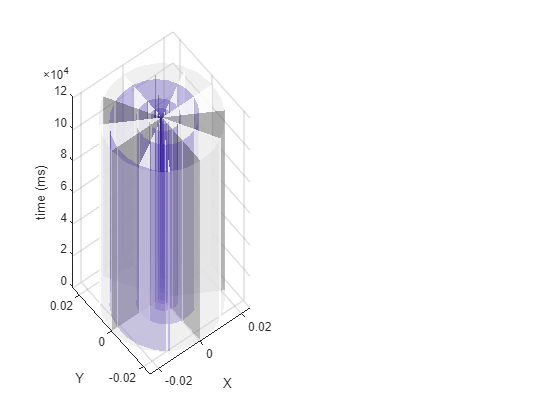

% drawing two graph
tiledlayout(1,2)
ax_3D = nexttile(1);

% drawing cyinders
[x y z_c] = cylinder(R);
ax_3D_cyl = surf(x, y, z_c*(H),'FaceColor',[.8 .8 .8],'EdgeAlpha',0, 'FaceAlpha',.3);
hold on;

% drawing spiral surf
P = 2; % parted

f_P = f_i*r.^(-32+note_i:1/P:N-2);
theta_P = pi/2 - 2*pi*log2(f_P/f_i);
A_P = 1./f_P;

[x y] = pol2cart(theta_P, A_P);
z_s = zeros(1, length(x));
ax_3D_spir = surf([x; x], [y; y], [z_s; z_s+H],'EdgeAlpha',0, 'FaceAlpha',.3);

% drawing white key
[xw yw] = pol2cart(wk, R);
[xb yb] = pol2cart(bk, R);

zero = zeros(1, length(xw));
x = reshape([zero; xw],1,[]);
y = reshape([zero; yw],1,[]);
z_w = zeros(1, length(xw)*2);
ax_3D_wk = surf([x; x], [y; y], [z_w;z_w+H],'FaceColor','w', 'FaceAlpha',.8, 'EdgeAlpha',0);

% drawing black key
zero = zeros(1, length(xb));
x = reshape([zero; xb],1,[]);
y = reshape([zero; yb],1,[]);
z_b = zeros(1, length(xb)*2);

ax_3D_bk = surf([x; x], [y; y], [z_b;z_b+H],'FaceColor','black', 'FaceAlpha',.3, 'EdgeAlpha',0);

xlabel('X')
ylabel('Y')
zlabel('time (ms)')

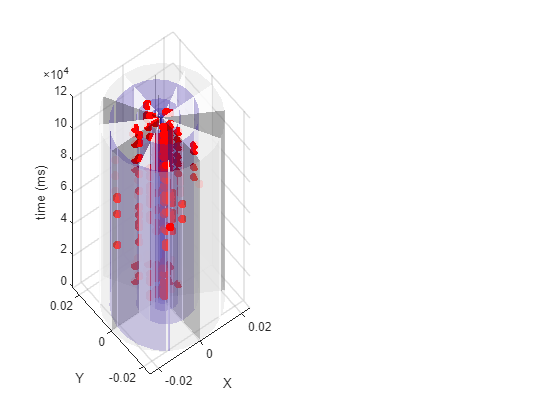

tic
note_length = length(only_on_list);

% Piano Note

n = only_on_list(:, 1); st = only_on_list(:, 3).'; et = only_on_list(:, 4).';

idx = n - note_i;

[x, y] = pol2cart(theta(idx), A(idx));

for i = 1:note_length
    plot3(x(i),y(i),st(i),'ro', 'MarkerFaceColor', 'r');
    plot3([x(i), x(i)], [y(i), y(i)], [st(i), et(i)], 'r-', 'LineWidth', 3);
end


toc

경과 시간은 1.306425초입니다.


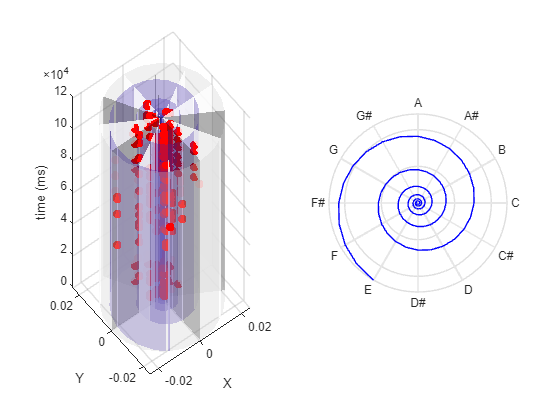

tic
% Second Gragh (2D Sheet)
ax_2D = nexttile(2);

for i=1:7 % white key
    polarplot([0 wk(i)],[0 R],'color',[.9 .9 .9],'linewidth',1.5)
    hold on
end

for i=1:5 % black key
    polarplot([0 bk(i)],[0 R],'color',[.9 .9 .9],'linewidth',0.1) % Color include alpha value
    hold on
end

polarplot(theta_P, A_P,'b-')
rlim([0 R])
set(gca,'thetaticklabel',{'C' 'B' 'A#' 'A' 'G#' 'G' 'F#' 'F' 'E' 'D#' 'D' 'C#' })
set(gca,'rticklabel',[])

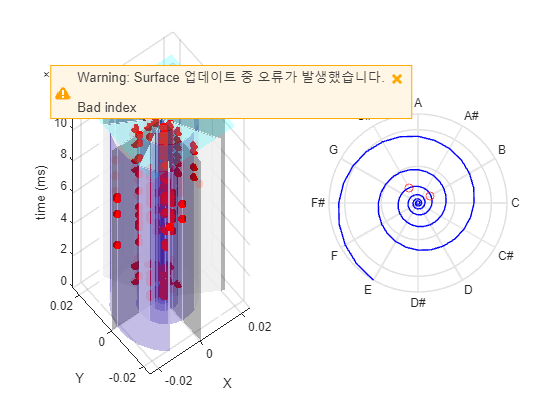

1
2
3
4


Error
Error
Error
Error


4
5


Error
Error
Error
Error
Error
Error


6


Error
Error
Error
Error
Error


7
8


Error
Error
Error
Error
Error
Error
Error
Error


9


Error
Error
Error
Error
Error


10


Error
Error
Error
Error
Error
Error
Error
Error


11


Error
Error
Error
Error
Error
Error


11


Error
Error
Error
Error
Error
Error
Error
Error


12


Error
Error
Error
Error
Error
Error
Error
Error


13
14


Error
Error
Error
Error
Error
Error


15


Error
Error
Error
Error
Error


16


Error
Error


17


Error
Error
Error
Error
Error
Error
Error
Error


18


Error
Error
Error


18
19


Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error


20


Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error


21
22
23
24
25
25
26
27
28
29
30
31
32
33
33
34
35
36
37
38
39


Error
Error
Error
Error
Error


40
40
41


Error
Error
Error


42


Error
Error
Error
Error


43


Error
Error
Error
Error
Error
Error
Error
Error
Error


44


Error


45


Error
Error
Error
Error
Error
Error
Error


46


Error
Error
Error
Error


47


Error


47


Error
Error
Error
Error
Error
Error


48
49


Error
Error
Error
Error
Error
Error
Error
Error


50
51


Error
Error
Error
Error
Error
Error
Error


52


Error
Error
Error
Error
Error
Error
Error
Error
Error


53


Error
Error
Error
Error
Error
Error


54


Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error


54
55
56


Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error


57


Error
Error
Error
Error
Error


58


Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error


59


Error
Error
Error


60


Error
Error
Error
Error
Error


61


Error
Error
Error
Error
Error
Error
Error
Error


62


Error
Error
Error
Error
Error
Error
Error
Error
Error
Error


62


Error
Error
Error
Error
Error
Error
Error
Error


63


Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error


64


Error
Error
Error
Error
Error
Error
Error


65


Error
Error
Error
Error
Error
Error
Error
Error
Error


66


Error
Error
Error


67


Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error


68
69
69


Error
Error
Error
Error
Error
Error
Error
Error


70
71


Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error


72


Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error


73


Error
Error
Error
Error
Error
Error
Error
Error


74


Error
Error
Error
Error
Error
Error
Error
Error
Error
Error


75


Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error


76


Error
Error
Error
Error
Error
Error
Error
Error
Error


76


Error
Error
Error
Error
Error
Error
Error


77


Error
Error
Error


78


Error
Error
Error
Error
Error
Error
Error


79


Error
Error
Error
Error
Error
Error
Error
Error


80


Error
Error
Error
Error
Error
Error
Error
Error
Error
Error


81


Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error


82


Error
Error
Error
Error
Error
Error
Error
Error
Error


83


Error
Error
Error


83


Error
Error
Error
Error
Error
Error
Error
Error


84


Error
Error
Error
Error
Error
Error
Error


85


Error
Error
Error
Error
Error
Error
Error
Error


86


Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error


87
88


Error
Error
Error
Error
Error
Error
Error


89


Error
Error
Error
Error
Error
Error


90


Error
Error
Error
Error
Error
Error


90


Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error


91
92


Error
Error
Error
Error
Error
Error
Error


93


Error
Error
Error
Error
Error


94


Error
Error
Error
Error
Error
Error


95


Error
Error
Error
Error
Error


96
97
98


Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error
Error


98


Error
Error
Error
Error
Error
Error


99


video_frame = 15;

video = VideoWriter('신호등.avi');
video.FrameRate = video_frame;
open(video);

max_note = length(theta);
f = f_i*r.^(-32+note_i:N-2);
theta = pi/2 - 2*pi*log2(f/f_i); % Clock Convention
A = 1./f;

on_note = [];
on_size = 1;

m_x = -0.02:0.01:0.02;
m_y = m_x;
[X, Y, Z] = meshgrid(m_x, m_y, 0);

Z_plane = surf(ax_3D, X,Y,Z, 'FaceColor','c','FaceAlpha',.2, 'EdgeAlpha',0);

x = 0;
y = 0;
p = polarplot(x,y,'o');
p.Color = "red";
t_frame = round(1000 / video_frame);

note_index = 1;
note_time = note_list(note_index, 4);

note_list_length = length(note_list);

% Piano Note
for t=1:total_time
    if rem(t, 1000) == 0
        fprintf('%.0f\n', t*100/total_time);
    end

    if rem(t, t_frame) == 0
        f = getframe(gcf);
        writeVideo(video, f);
    end
    
    if t > note_time
        fprintf('Error\n');
    end

    if t >= note_time
        
        note = note_list(note_index, :);
        note_index = note_index + 1;

        if note_index > note_list_length
            break;
        end
        
        note_time = note_list(note_index, 4);
        
        if note(1) == 1
            on_note(on_size) = note(2);
            on_size = on_size + 1;
        else
            off_index = (on_note == note(2));
            on_note(off_index) = [];
            on_size = on_size - 1;
        end
        
        zero_index = (on_note == 0);
        on_note(zero_index) = [];
        
        idx = on_note - note_i;
        
        if ~(isempty(idx))
            p.XData = theta(idx);
            p.YData = A(idx);
        else
            p.XData = [];
            p.YData = [];
        end
        
    end
    if rem(t, t_frame) == 0
        ax_3D_spir.ZData = [z_s; z_s+t];
        ax_3D_bk.ZData = [z_b; z_b+t];
        ax_3D_wk.ZData = [z_w; z_w+t];
        ax_3D_cyl.ZData = [z_c; z_c+t];
        Z_plane.ZData = zeros(5, 5)+t;
    end
    drawnow;
end

close(video);
toc

경과 시간은 1574.315951초입니다.


## Synthesize MIDI Messages

This example plays parsed MIDI messages using a simple monophonic synthesizer. To see a demonstration of this synthesizer, see [Design and Play a MIDI Synthesizer](docid:audio_ug#mw_9cb34f1f-767f-42a8-b6c7-c33d9546923a). 

% Initialize System objects for playing MIDI messages
%osc = audioOscillator('square', 'Amplitude', 0,'DutyCycle',0.75);
%deviceWriter = audioDeviceWriter;

% - - Play Audio
%simplesynth(msgArray,osc,deviceWriter);

You can also send parsed MIDI messages to a MIDI device using [`midisend`](docid:audio_ref#mw_ee7bc3c1-86e5-4047-92ee-d8c60dfac44d). For more information about interacting with MIDI devices using MATLAB, see [MIDI Device Interface](docid:audio_ug#mw_66a38da2-303f-4ffe-9948-e67eb0d3fdd6).

## Helper Functions

### Read Delta-Times

function [valueOut,byteLength] = findVariableLength(lengthIndex,readOut)

byteStream = zeros(4,1);

for i = 1:4
    valCheck = readOut(lengthIndex+i);
    byteStream(i) = bitand(valCheck,127);   % Mask MSB for value
    if ~bitand(valCheck,uint32(128))        % If MSB is 0, no need to append further
        break
    end
end

valueOut = polyval(byteStream(1:i),128);    % Base is 128 because 7 bits are used for value
byteLength = i;

end

### Interpret MIDI Messages

function [statusOut,lenOut,message] = interpretMessage(statusIn,eventIn,readOut)

% Check if running status
introValue = readOut(eventIn+1);
if isStatusByte(introValue)
    statusOut = introValue;         % New status
    running = false;
else
    statusOut = statusIn;           % Running status—Keep old status
    running = true;
end

switch statusOut
    case 255     % Meta-event (FF)—IGNORE
        [eventLength, lengthLen] = findVariableLength(eventIn+2, ...
            readOut);   % Meta-events have an extra byte for type of meta-event
        lenOut = 2+lengthLen+eventLength;
        message = -1;
    case 240     % Sysex message (F0)—IGNORE
        [eventLength, lengthLen] = findVariableLength(eventIn+1, ...
            readOut);
        lenOut = 1+lengthLen+eventLength;
        message = -1;
        
    case 247     % Sysex message (F7)—IGNORE
        [eventLength, lengthLen] = findVariableLength(eventIn+1, ...
            readOut);
        lenOut = 1+lengthLen+eventLength;
        message = -1;
    otherwise    % MIDI message—READ
        eventLength = msgnbytes(statusOut);
        if running  
            % Running msgs don't retransmit status—Drop a bit
            lenOut = eventLength-1;
            message = uint8([statusOut;readOut(eventIn+(1:lenOut))]);
            
        else
            lenOut = eventLength;
            message = uint8(readOut(eventIn+(1:lenOut)));
        end
end

end

% ----

function n = msgnbytes(statusByte)

if statusByte <= 191        % hex2dec('BF')
    n = 3;
elseif statusByte <= 223    % hex2dec('DF')
    n = 2;
elseif statusByte <= 239    % hex2dec('EF')
    n = 3;
elseif statusByte == 240    % hex2dec('F0')
    n = 1;
elseif statusByte == 241    % hex2dec('F1')
    n = 2;
elseif statusByte == 242    % hex2dec('F2')
    n = 3;
elseif statusByte <= 243    % hex2dec('F3')
    n = 2;
else
    n = 1;
end

end

% ----

function yes = isStatusByte(b)
yes = b > 127;
end

### Create MIDI Messages

function [tsOut,msgOut] = createMessage(messageIn,tsIn,deltaTimeIn,ticksPerQNoteIn,bpmIn)

if messageIn < 0     % Ignore Sysex message/meta-event data
    tsOut = tsIn;
    msgOut = midimsg(0);
    return
end

% Create RawBytes field
messageLength = length(messageIn);
zeroAppend = zeros(8-messageLength,1);
bytesIn = transpose([messageIn;zeroAppend]);

% deltaTimeIn and ticksPerQNoteIn are both uints
% Recast both values as doubles
d = double(deltaTimeIn);
t = double(ticksPerQNoteIn);

% Create Timestamp field and tsOut
msPerQNote = 6e7/bpmIn;
timeAdd = d*(msPerQNote/t)/1e6;
tsOut = tsIn+timeAdd;

% Create midimsg object
midiStruct = struct('RawBytes',bytesIn,'Timestamp',tsOut);
msgOut = midimsg.fromStruct(midiStruct);

end

## Play MIDI Messages Using a Synthesizer

function simplesynth(msgArray,osc,deviceWriter)

i = 1;
tic
endTime = msgArray(length(msgArray)).Timestamp;

while toc < endTime
    if toc >= msgArray(i).Timestamp     % At new note, update deviceWriter
        msg = msgArray(i);      
        i = i+1;
        if isNoteOn(msg)
            osc.Frequency = note2freq(msg.Note);
            osc.Amplitude = msg.Velocity/127;
        elseif isNoteOff(msg)
            if msg.Note == msg.Note
                osc.Amplitude = 0;
            end
        end
    end
    deviceWriter(osc());    % Keep calling deviceWriter as it is updated
end

end

% ----

function yes = isNoteOn(msg)
yes = strcmp(msg.Type,'NoteOn') ...
    && msg.Velocity > 0;
end

% ----

function yes = isNoteOff(msg)
yes = strcmp(msg.Type,'NoteOff') ...
    || (strcmp(msg.Type,'NoteOn') && msg.Velocity == 0);
end

% ----

function freq = note2freq(note)
freqA = 440;
noteA = 69;
freq = freqA * 2.^((note-noteA)/12);
end

*Copyright 2018 The MathWorks, Inc.*